# Modelo SIR tradução - Enrico Giannobile 19.00610-0

## Boas práticas

clear all;
close all;
clc;


## Leitura de dados

T = readtable('SIRpd.csv');    % Lendo dados csv e transformando em tabela
T = table2array(T);            % Transformando tabela em array

%% Indexando cada parte da tabela para separar S R e I
Sd = T(:,1);                   
Id = T(:,2);
Rd = T(:,3);

## Gerando ruído para os dados amostrados

Sdn = 20.*randn(1000,1);

Idn = 10.*randn(1000,1);

Rdn = 20.*randn(1000,1); 

## Somando dados amostrados e ruído


Sd = Sd + Sdn;
Id = Id + Idn;
Rd = Rd + Rdn;

## Chamando modelo SIR  (Simulink)

%% Tamanho da população - N
N = 500;

%% Valores iniciais do modelo
i0 = 1;
r0 = 0;
s0 = N - i0;

%% Vetor de condições iniciais

y0 = [s0 i0 r0];

global r;
global beta;

theta0 = [1e-4,1e-2]; % valores iniciais
beta = theta0(1);     % taxa de contato
r = theta0(2);        % taxa média de recuperação (in 1/dia)

%% Definição de configurações do modelo

t = linspace(0,1000,1000); %*

mdl = 'SimulacaoSIR';
load_system(mdl)
cs = getActiveConfigSet(mdl);
mdl_cs = cs.copy;
set_param(mdl_cs,'AbsTol','1e-5',...
         'SaveState','on','StateSaveName','xoutNew',...
         'SaveOutput','on','OutputSaveName','youtNew');
simOut = sim(mdl, mdl_cs);

## Visualizando a evolução da Epidemia

## (Dados amostrados x Dados modelados)

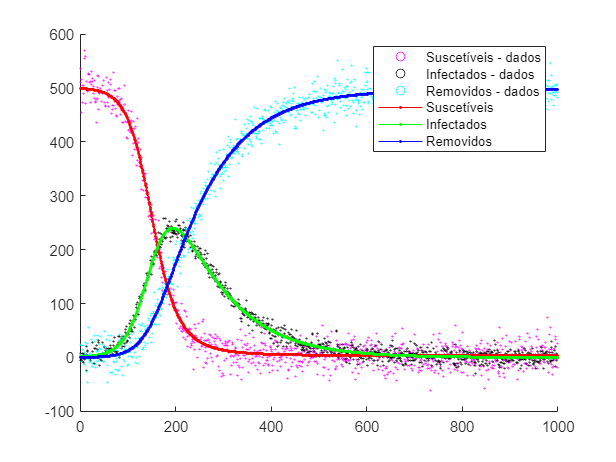

%% Saídas do modelo 
S = simOut.logsout{1}.Values.Data;  
I = simOut.logsout{2}.Values.Data;
R = simOut.logsout{3}.Values.Data;

%% Plotagem dos dados
t = linspace(0,length(S),length(S));
td = linspace(0,length(Sd), length(Sd));

figure(1)

scatter(td,Sd, 0.8, 'magenta')
hold on;
scatter(td,Id, 0.8, 'black')
scatter(td,Rd, 0.8, 'cyan')
plot(t, S, marker='.', color='r')
plot(t, I, marker='.', color='g')
plot(t, R, marker='.', color='b')


legend('Suscetíveis - dados', 'Infectados - dados', 'Removidos - dados', 'Suscetíveis', 'Infectados', 'Removidos')
xlabel = ('Dias');
ylabel = ('Indivíduos');
hold off;

## Minimizando erro

ErroQuadratico(theta0, Sd, Id, Rd)  % Erro inicial

Eq = 9.0353e+05

ans = 9.0353e+05

format long;
X = fminsearch(@(x) ErroQuadratico(x, Sd, Id, Rd), theta0)

Eq =      9.035300669060244e+05


Eq =      1.138082885949022e+06


Eq =      9.365400608925000e+05


Eq =      1.311347878430627e+06


Eq =      9.604777176447405e+05


Eq =      1.023055966890193e+06


Eq =      9.197204902168557e+05


Eq =      9.247523100199939e+05


Eq =      9.103545205614460e+05


Eq =      9.064995449019638e+05


Eq =      9.205377096313087e+05


Eq =      9.035698642102040e+05


Eq =      9.108553063023845e+05


Eq =      9.029026033965368e+05


Eq =      9.059786659431283e+05


Eq =      9.024371950891271e+05


Eq =      9.059277995146636e+05


Eq =      9.024360367763417e+05


Eq =      9.034259602827821e+05


Eq =      9.023960042052204e+05


Eq =      9.027454054230000e+05


Eq =      9.023105189889017e+05


Eq =      9.027565952849798e+05


Eq =      9.023124305331034e+05


Eq =      9.024292298640305e+05


Eq =      9.023182174601944e+05


Eq =      9.023353105739709e+05


Eq =      9.023009979782433e+05


Eq =      9.023584087641077e+05


Eq =      9.022983972787457e+05


Eq =      9.023212521872553e+05


Eq =      9.023000470576689e+05


Eq =      9.023014467033250e+05


Eq =      9.022983982455265e+05


Eq =      9.023030067903465e+05


Eq =      9.022979495591944e+05


Eq =      9.022985466713931e+05


Eq =      9.022977214256092e+05


Eq =      9.023008982766124e+05


Eq =      9.022975913754313e+05


Eq =      9.022983532768143e+05


Eq =      9.022976286770049e+05


Eq =      9.022975220512708e+05


Eq =      9.022977057977327e+05


Eq =      9.022980007140335e+05


Eq =      9.022975122801611e+05


Eq =      9.022975585821952e+05


Eq =      9.022975092386955e+05


Eq =      9.022975858731593e+05


Eq =      9.022974994716850e+05


Eq =      9.022975452293740e+05


Eq =      9.022974997833886e+05


Eq =      9.022975048192132e+05


Eq =      9.022974986396010e+05


Eq =      9.022975085281805e+05


Eq =      9.022974973454415e+05


Eq =      9.022975027886324e+05


Eq =      9.022974976477502e+05


Eq =      9.022974982773985e+05


Eq =      9.022974974360729e+05


Eq =      9.022974983329503e+05


Eq =      9.022974972657026e+05


Eq =      9.022974974815090e+05


Eq =      9.022974972489225e+05


X =     0.0001    0.0099




beta = X(1)

beta =      1.000716701846154e-04


r = X(2)

r =    0.009895495441430



simOut_2 = sim(mdl, mdl_cs);

## (Dados amostrados x Dados ajustados)

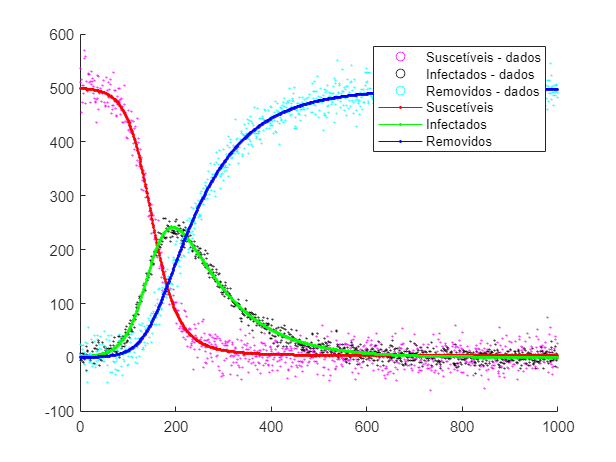



%% Saídas do modelo 
S_2 = simOut_2.logsout{1}.Values.Data;  
I_2 = simOut_2.logsout{2}.Values.Data;
R_2 = simOut_2.logsout{3}.Values.Data;

%% Plotagem dos dados
t = linspace(0,length(S),length(S));
td = linspace(0,length(Sd), length(Sd));

figure(2)

scatter(td,Sd, 0.8, 'magenta')
hold on;
scatter(td,Id, 0.8, 'black')
scatter(td,Rd, 0.8, 'cyan')
plot(t, S_2, marker='.', color='r')
plot(t, I_2, marker='.', color='g')
plot(t, R_2, marker='.', color='b')


legend('Suscetíveis - dados', 'Infectados - dados', 'Removidos - dados', 'Suscetíveis', 'Infectados', 'Removidos')
xlabel = ('Dias');
ylabel = ('Indivíduos');
hold off;